## Radiator Transient Model - Constant Condition Validation

% Runs the transient forward-Euler model under held-constant RPM/Torque/v_air
% and checks convergence against an independent steady-state solve (fzero)
% of Q_gen = Q_rejected(T_ss). This validates the ODE integration against
% the already-verified steady epsilon-NTU function before touching real telemetry.
clear; clc; close all;

%% Efficiency map (same data as radiator_transient.mlx)
rpm_pts = [2000 4000 6000 8000 10000 12000, ...
    2000 4000 6000 8000 10000 12000 14000, ...
    2000 4000 6000 8000 10000 12000 14000 16000, ...
    2000 4000 6000 8000 10000 12000 14000 16000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000 20000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000 20000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000 20000 22000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000 20000 22000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000 20000 22000 24000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000 20000 22000 24000, ...
    2000 4000 6000 8000 10000 12000 14000 16000 18000 20000 22000 24000];

torque_pts = [26 26 26 26 26 26, ...
    24 24 24 24 24 24 24, ...
    22 22 22 22 22 22 22 22, ...
    20 20 20 20 20 20 20 20, ...
    18 18 18 18 18 18 18 18 18, ...
    16 16 16 16 16 16 16 16 16, ...
    14 14 14 14 14 14 14 14 14 14, ...
    12 12 12 12 12 12 12 12 12 12, ...
    10 10 10 10 10 10 10 10 10 10 10, ...
    8  8  8  8  8  8  8  8  8  8  8, ...
    6  6  6  6  6  6  6  6  6  6  6  6, ...
    4  4  4  4  4  4  4  4  4  4  4  4, ...
    2  2  2  2  2  2  2  2  2  2  2  2];

eff_pts = [73 82 88 91 93 93, ...
    74 84 89 91 93 93 94, ...
    75 85 89 92 93 94 94 94, ...
    77 86 90 92 94 94 94 94, ...
    78 87 90 92 94 94 94 94 94, ...
    80 88 90 93 94 94 94 94 94, ...
    81 88 92 94 94 94 94 94 94 94, ...
    82 89 92 94 94 94 94 94 94 94, ...
    83 89 92 94 94 95 95 94 94 93 93, ...
    85 90 92 94 94 95 94 93 93 93 93, ...
    86 91 93 94 94 94 94 94 93 92 92 91, ...
    87 92 93 94 93 94 94 94 92 92 92 91, ...
    88 93 93 94 93 94 93 93 92 91 91 90] / 100;

F = scatteredInterpolant(rpm_pts(:), torque_pts(:), eff_pts(:), 'linear', 'nearest');


## Fixed geometry and properties

% CHANGE HERE
A_face_fixed = 0.0286;
fpi_fixed = 18;
H_fixed = 0.35; %(m)
d = 0.032; %(m), depth of radiator
mdot_coolant = 10; %(L/min), per side
T_air_in = 25; %(degC)

import py.CoolProp.CoolProp.*

a_tube = 0.002; b_tube = d; tube_pitch = 0.010;
D_h_tube = (4*a_tube*b_tube)/(2*(a_tube+b_tube));
A_tube = a_tube*b_tube;
f_height = 0.008; f_thickness = 0.00008;
k_fin = 237;

T_air_K = 298.15; P_air = 101325;
rho_air = PropsSI('D','T',T_air_K,'P',P_air,'Air');
mu_air  = PropsSI('V','T',T_air_K,'P',P_air,'Air');
k_air   = PropsSI('L','T',T_air_K,'P',P_air,'Air');
cp_air  = PropsSI('C','T',T_air_K,'P',P_air,'Air');
Pr_air  = PropsSI('Prandtl','T',T_air_K,'P',P_air,'Air');

P_water = 101325;
rho_water = PropsSI('D','T',323.15,'P',P_water,'Water');
cp_water  = PropsSI('C','T',323.15,'P',P_water,'Water');

mdot_coolant_kgs = (mdot_coolant*rho_water)/60000; % L/min -> kg/s

props = struct('T_air_in',T_air_in,'rho_air',rho_air,'mu_air',mu_air,'k_air',k_air, ...
    'cp_air',cp_air,'Pr_air',Pr_air,'rho_water',rho_water,'cp_water',cp_water, ...
    'd',d,'a_tube',a_tube,'A_tube',A_tube,'D_h_tube',D_h_tube, ...
    'tube_pitch',tube_pitch,'f_height',f_height, ...
    'f_thickness',f_thickness,'k_fin',k_fin);

n_tubes = floor(H_fixed/tube_pitch);
m_water = props.rho_water*props.A_tube*(A_face_fixed/H_fixed)*n_tubes;


## Test case matrix

% Case A: zero load, expect T -> T_air_in
% Case B: nominal design point, mid-map efficiency
% Case C: overload, max torque + low rpm + floored v_air, expect runaway (no steady solution)
% Case D: same as B but approached from above (T_initial > expected T_ss)
% Case E: nominal Q_gen swept across three v_air values, expect monotonic T_ss decrease
cases = struct('label',{},'rpm',{},'torque',{},'v_air',{},'T_initial',{},'duration',{},'dt',{});

cases(1) = struct('label','A: zero load','rpm',5000,'torque',0,'v_air',10,'T_initial',25,'duration',1200,'dt',1);
cases(2) = struct('label','B: nominal design point','rpm',8000,'torque',20,'v_air',10,'T_initial',25,'duration',1800,'dt',1);
cases(3) = struct('label','C: overload (stall, max torque, floored air)','rpm',2000,'torque',26,'v_air',0.5,'T_initial',25,'duration',1800,'dt',1);
cases(4) = struct('label','D: nominal, approached from above','rpm',8000,'torque',20,'v_air',10,'T_initial',80,'duration',1800,'dt',1);
cases(5) = struct('label','E1: nominal Q_gen, v_air=5','rpm',8000,'torque',20,'v_air',5,'T_initial',25,'duration',1800,'dt',1);
cases(6) = struct('label','E2: nominal Q_gen, v_air=15','rpm',8000,'torque',20,'v_air',15,'T_initial',25,'duration',1800,'dt',1);
cases(7) = struct('label','E3: nominal Q_gen, v_air=30','rpm',8000,'torque',20,'v_air',30,'T_initial',25,'duration',1800,'dt',1);


## Run each case

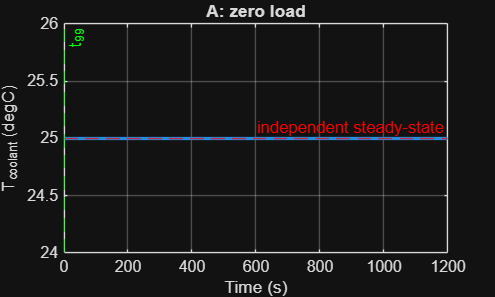

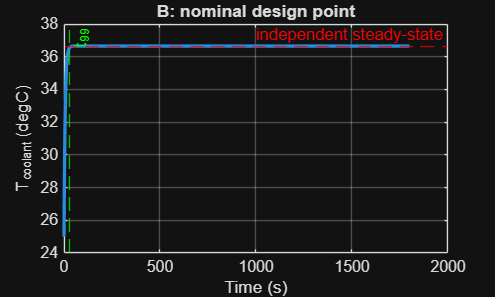

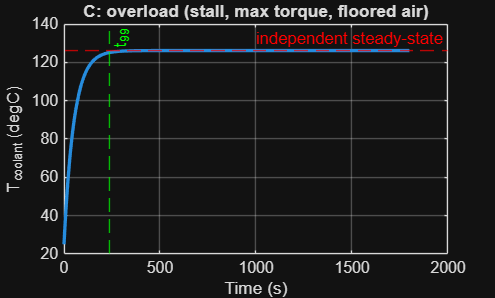

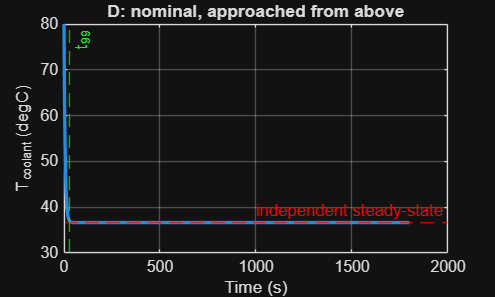

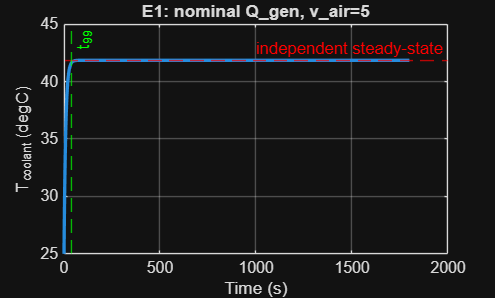

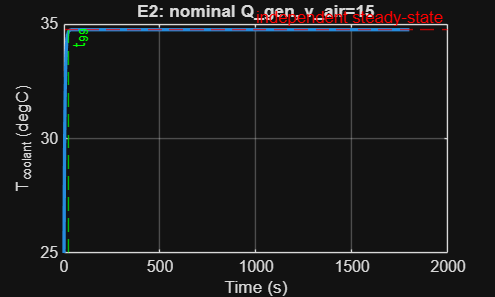

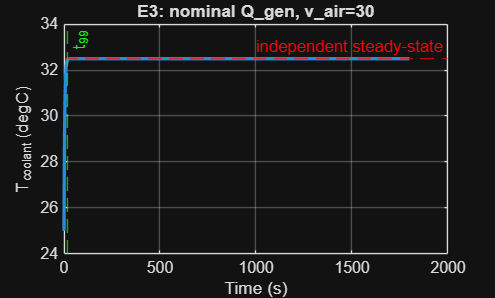

results = struct('label',{},'Q_gen',{},'T_final_sim',{},'T_ss_independent',{},'diff',{},'tau_est',{},'t99',{},'status',{});

for i = 1:length(cases)
    c = cases(i);
    power = c.torque*c.rpm*2*pi/60;
    eff = F(c.rpm, c.torque);
    eff = min(max(eff, 0), 1);
    Q_gen = power*(1-eff);

    N = round(c.duration/c.dt);
    T_old = c.T_initial;
    T_hist = zeros(N,1);
    T_hist(1) = T_old;
    water_state = [];

    for k = 1:N-1
        [Q_rejected, water_state] = Q_epsilonNTU(T_old, c.v_air, mdot_coolant_kgs, A_face_fixed, fpi_fixed, H_fixed, props, water_state);
        T_new = T_old + c.dt*(Q_gen-Q_rejected)/(m_water*cp_water);
        T_hist(k+1) = T_new;
        T_old = T_new;
    end

    T_final_sim = T_hist(end);

    % independent steady-state solve: R(T) = Q_gen - Q_rejected(T)
    % bisection method
    residual = @(T) Q_gen-Q_epsilonNTU(T, c.v_air, mdot_coolant_kgs, A_face_fixed, fpi_fixed, H_fixed, props, []);
    T_lo = T_air_in+0.01; % bounds for temp search range, temp cant be below t_air
    T_hi = 150; % 150 taken as an upper bound as coolant never reaches this 
    R_lo = residual(T_lo);
    R_hi = residual(T_hi);

    if Q_gen == 0 % no heat load means the coolant just relaxes to ambient air temp
        T_ss = T_air_in;
        status = 'converged';
        diff_val = T_final_sim-T_ss;
    else
        T_lo = T_air_in+0.01; 
        T_hi = 150; 
        R_lo = residual(T_lo);
        R_hi = residual(T_hi);

        if sign(R_lo) == sign(R_hi)
            T_ss = NaN;
            status = 'NO STEADY SOLUTION (overload) - check T_final_sim is monotonically rising';
            diff_val = NaN;
        else
            T_ss = fzero(residual, [T_lo T_hi]);
            status = 'converged';
            diff_val = T_final_sim-T_ss;
        end
    end

    [~, ~, UA_final] = Q_epsilonNTU(T_final_sim, c.v_air, mdot_coolant_kgs, A_face_fixed, fpi_fixed, H_fixed, props, []);
    tau_est = m_water*cp_water/UA_final;

    % time to reach 99% of the way from T_initial to the independent steady-state temp
    if isnan(T_ss)
        t99 = NaN; % no steady state to settle towards (overload case)
    elseif T_ss == c.T_initial
        t99 = 0; % already starting at steady state
    else
        T_target99 = c.T_initial + 0.99*(T_ss-c.T_initial);
        if T_ss > c.T_initial
            idx99 = find(T_hist >= T_target99, 1, 'first');
        else
            idx99 = find(T_hist <= T_target99, 1, 'first');
        end
        if isempty(idx99)
            t99 = NaN; % never reached 99% within the simulated duration
        elseif idx99 == 1
            t99 = 0;
        else
            t_lo = (idx99-2)*c.dt; t_hi = (idx99-1)*c.dt;
            T_lo_pt = T_hist(idx99-1); T_hi_pt = T_hist(idx99);
            frac = (T_target99-T_lo_pt)/(T_hi_pt-T_lo_pt);
            t99 = t_lo+frac*(t_hi-t_lo);
        end
    end

    results(i).label = c.label;
    results(i).Q_gen = Q_gen;
    results(i).T_final_sim = T_final_sim;
    results(i).T_ss_independent = T_ss;
    results(i).diff = diff_val;
    results(i).tau_est = tau_est;
    results(i).t99 = t99;
    results(i).status = status;

    figure;
    plot((0:N-1)*c.dt, T_hist, 'LineWidth', 2); hold on;
    if ~isnan(T_ss)
        yline(T_ss, 'r--', 'independent steady-state');
    end
    if ~isnan(t99)
        xline(t99, 'g--', 't_{99}');
    end
    xlabel('Time (s)'); ylabel('T_{coolant} (degC)');
    title(c.label, 'Interpreter', 'none');
    grid on;
end

## Summary table

fprintf('\n%-45s %10s %10s %10s %10s %8s %8s   %s\n', 'Case', 'Q_gen(W)', 'T_sim(C)', 'T_ss(C)', 'diff(C)', 'tau(s)', 't99(s)', 'status');


Case                                            Q_gen(W)   T_sim(C)    T_ss(C)    diff(C)   tau(s)   t99(s)   status


for i = 1:length(results)
    r = results(i);
    fprintf('%-45s %10.1f %10.2f %10.2f %10.3f %8.1f %8.1f   %s\n', r.label, r.Q_gen, r.T_final_sim, r.T_ss_independent, r.diff, r.tau_est, r.t99, r.status);
end

A: zero load                                         0.0      25.00      25.00      0.000      4.7      0.0   converged
B: nominal design point                           1340.4      36.65      36.65      0.004      4.7     27.7   converged
C: overload (stall, max torque, floored air)      1470.3     126.16     126.16      0.001     22.7    237.6   converged
D: nominal, approached from above                 1340.4      36.65      36.65     -0.003      4.7     27.7   converged
E1: nominal Q_gen, v_air=5                        1340.4      41.85      41.85      0.004      6.4     41.2   converged
E2: nominal Q_gen, v_air=15                       1340.4      34.75      34.75      0.001      4.0     22.8   converged
E3: nominal Q_gen, v_air=30                       1340.4      32.49      32.49      0.004      3.2     16.9   converged


fprintf('\nCheck: |diff| should be small (sub-0.1 C) for cases A,B,D,E1-E3 if dt << tau.\n');


Check: |diff| should be small (sub-0.1 C) for cases A,B,D,E1-E3 if dt << tau.


fprintf('Check: Case C should show status NO STEADY SOLUTION with T_final_sim still rising at end of run.\n');

Check: Case C should show status NO STEADY SOLUTION with T_final_sim still rising at end of run.


fprintf('Check: E1 > E2 > E3 in T_ss (higher v_air rejects more heat, so converges cooler).\n');

Check: E1 > E2 > E3 in T_ss (higher v_air rejects more heat, so converges cooler).


fprintf('Check: Case D T_final_sim should land at the same T_ss as case B, approached from above.\n');

Check: Case D T_final_sim should land at the same T_ss as case B, approached from above.


fprintf('Check: t99 ~ 4.6*tau for a first-order response (ln(100) ~= 4.6) when dt << tau.\n');

Check: t99 ~ 4.6*tau for a first-order response (ln(100) ~= 4.6) when dt << tau.


## Local function: steady epsilon-NTU heat rejection

function [Q_rejected, water_state, UA] = Q_epsilonNTU(T_coolant_in, v_air, mdot_coolant_kgs, A_face, fpi, H, props, water_state)
import py.CoolProp.CoolProp.*
if isempty(water_state) || abs(T_coolant_in-water_state.T_last) >= 1
    P_water = 101325;
    water_state.T_last = T_coolant_in;
    water_state.k_water = PropsSI('L','T',T_coolant_in+273.15,'P',P_water,'Water');
    water_state.mu_water = PropsSI('V','T',T_coolant_in+273.15,'P',P_water,'Water');
    water_state.Pr_water = PropsSI('Prandtl','T',T_coolant_in+273.15,'P',P_water,'Water');
end
k_water = water_state.k_water;
mu_water = water_state.mu_water;
Pr_water = water_state.Pr_water;

n_tubes = floor(H/props.tube_pitch);
mdot_tube = mdot_coolant_kgs/n_tubes;
v_water = mdot_tube/(props.rho_water*props.A_tube);
Re_water = (props.rho_water*v_water*props.D_h_tube)/mu_water;
if Re_water < 2300
    Nu_water = 3.66;
else
    Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.3);
end
h_water = (Nu_water*k_water)/props.D_h_tube;

sigma_c = 1-((fpi*props.f_height*props.f_thickness)/0.0254+props.a_tube)/(props.a_tube+props.f_height);
G_air = props.rho_air*v_air/sigma_c;
f_spacing = 0.0254/fpi;
D_h_fin = (4*f_spacing*props.f_height)/(2*(f_spacing+props.f_height));
Re_air = G_air*D_h_fin/props.mu_air;
J_air = 0.174/(Re_air^0.383);
h_air = J_air*G_air*props.cp_air/(props.Pr_air^0.667);

U = 1/((1/h_air)+(1/h_water));

C_air = props.rho_air*v_air*props.cp_air*A_face;
C_water = mdot_coolant_kgs*props.cp_water;
C_min = min(C_air, C_water);
C_max = max(C_air, C_water);
C_star = C_min/C_max;

W = A_face/H;
A_primary = 2*props.d*W*n_tubes;
A_secondary = 2*props.f_height*props.d*fpi*W*n_tubes/0.0254;
m_fin = sqrt(2*h_air/(props.k_fin*props.f_thickness));
L_c = props.f_height/2;
eta_f = tanh(m_fin*L_c)/(m_fin*L_c);
eta_0 = 1-(A_secondary/(A_primary+A_secondary))*(1-eta_f);
A_fins = eta_0*(A_primary+A_secondary);

UA = U*A_fins;
NTU = UA/C_min;
epsilon = 1-exp((NTU^0.22/C_star)*(exp(-C_star*NTU^0.78)-1));

Q_rejected = epsilon*C_min*(T_coolant_in-props.T_air_in);
end